## Projekt HA1 MdR

clear
clc
close all

Definition der Variablen aus der Aufgabenstellung:

global m l k g k_reg M_0
m = 1;
l = 25;
k = 10;
g = 9.81;

Berechnung des Haltemoments aus Aufgabe 1

phi_0   = 105;
M_0     = m*g*l*sind(phi_0)

M_0 = 236.8933

Berechnung des Verstärkungsfaktors nach Aufgabe 6

D = 0.7;
omega = k/(2*D*m*l)

omega = 0.2857

k_reg = l^2*m*(omega^2-g/l*cosd(phi_0))

k_reg = 114.4958

## Aufgabe 7

### $\varphi \;$bei dt = 0.02 s mit dem Eulerverfahren

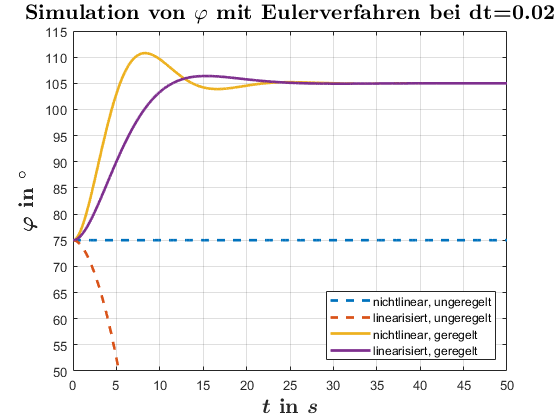

nichtlin_nichtreg_euler(k,l,m,g,k_reg,M_0,0.02,1)
lin_nichtreg_euler(k,l,m,g,k_reg,M_0,0.02,1)
nichtlin_reg_euler(k,l,m,g,k_reg,M_0,0.02,1)
lin_reg_euler(k,l,m,g,k_reg,M_0,0.02,1)
title("\textbf{Simulation von $\varphi$ mit Eulerverfahren bei dt=0.02}","Interpreter","latex","FontSize",16)
ylim([50 115])
xlim([0 50])
yticks(50:5:115)
ylabel("\textbf{\boldmath$\varphi$ in \boldmath$^\circ$}","Interpreter","latex","FontSize",16)
xlabel("\textbf{\boldmath$t$ in \boldmath$s$}","Interpreter","latex","FontSize",16)
legend("nichtlinear, ungeregelt", "linearisiert, ungeregelt", "nichtlinear, geregelt","linearisiert, geregelt","Location","southeast")
hold off

### $\dot{\varphi \;} \;$bei dt = 0.02 mit dem Eulerverfahren

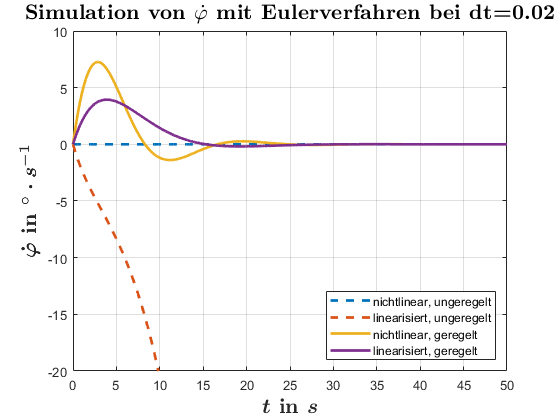

nichtlin_nichtreg_euler(k,l,m,g,k_reg,M_0,0.02,2)
lin_nichtreg_euler(k,l,m,g,k_reg,M_0,0.02,2)
nichtlin_reg_euler(k,l,m,g,k_reg,M_0,0.02,2)
lin_reg_euler(k,l,m,g,k_reg,M_0,0.02,2)
title("\textbf{Simulation von $\dot{\varphi}$ mit Eulerverfahren bei dt=0.02}","Interpreter","latex","FontSize",16)
ylim([-20 10])
xlim([0 50])
ylabel("\textbf{\boldmath$\dot{\varphi}$ in \boldmath$^\circ\cdot s^{-1}$}","Interpreter","latex","FontSize",16)
xlabel("\textbf{\boldmath$t$ in \boldmath$s$}","Interpreter","latex","FontSize",16)
%yticks(-5:5:115)
legend("nichtlinear, ungeregelt", "linearisiert, ungeregelt", "nichtlinear, geregelt","linearisiert, geregelt","Location","southeast")
hold off

%Verschiebung nichtlinearer plot komisch


### $u\;$bei dt = 0.02 mit dem Eulerverfahren

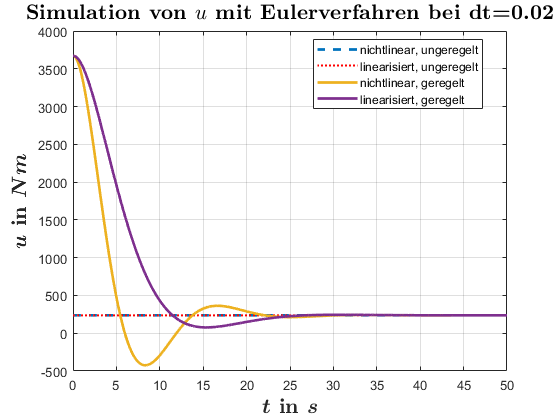

nichtlin_nichtreg_euler(k,l,m,g,k_reg,M_0,0.02,3)
lin_nichtreg_euler(k,l,m,g,k_reg,M_0,0.02,3)
nichtlin_reg_euler(k,l,m,g,k_reg,M_0,0.02,3)
lin_reg_euler(k,l,m,g,k_reg,M_0,0.02,3)
title("\textbf{Simulation von $u$ mit Eulerverfahren bei dt=0.02}","Interpreter","latex","FontSize",16)
%ylim([0 300])
xlim([0 50])
%yticks(-5:5:115)
ylabel("\textbf{\boldmath$u$ in \boldmath$Nm$}","Interpreter","latex","FontSize",16)
xlabel("\textbf{\boldmath$t$ in \boldmath$s$}","Interpreter","latex","FontSize",16)
legend("nichtlinear, ungeregelt", "linearisiert, ungeregelt", "nichtlinear, geregelt","linearisiert, geregelt","Location","best")
hold off

## Aufgabe 8

### $\varphi \;$ mit eulerverfahren:

figure("name","phi")
subplot(2,3,1)
lin_reg_euler(k,l,m,g,k_reg,M_0,0.1,1)
ylim([70 140])
ylabel("\textbf{\boldmath$\varphi$ in \boldmath$^\circ$}","Interpreter","latex","FontSize",12)
hold off
subplot(2,3,2)
lin_reg_euler(k,l,m,g,k_reg,M_0,4,1)
ylim([70 140])
xlabel("\textbf{\boldmath$t$ in \boldmath$s$}","Interpreter","latex","FontSize",12)
hold off
subplot(2,3,3)
lin_reg_euler(k,l,m,g,k_reg,M_0,8,1)
% ylim([50 150])
hold off

### $\varphi \;$ mit RK4

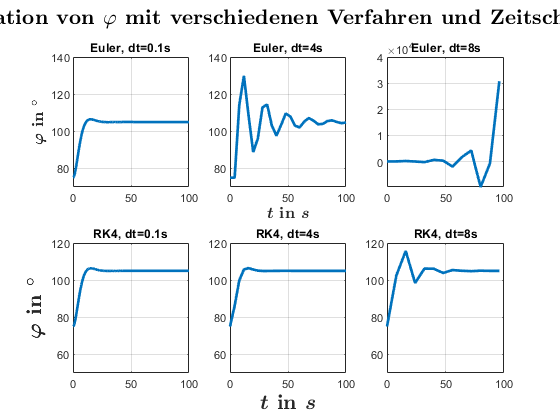

subplot(2,3,4)
lin_reg_ruku(k,l,m,g,k_reg,M_0,0.1,1)
ylim([50 120])
ylabel("\textbf{\boldmath$\varphi$ in \boldmath$^\circ$}","Interpreter","latex","FontSize",16)
hold off
subplot(2,3,5)
lin_reg_ruku(k,l,m,g,k_reg,M_0,4,1)
ylim([50 120])
xlabel("\textbf{\boldmath$t$ in \boldmath$s$}","Interpreter","latex","FontSize",16)
hold off
subplot(2,3,6)
lin_reg_ruku(k,l,m,g,k_reg,M_0,8,1)
ylim([50 120])
hold off
sgtitle("\textbf{Simulation von $\varphi$ mit verschiedenen Verfahren und Zeitschritten}","Interpreter","latex","FontSize",16)

### $\dot{\varphi \;} \;$ mit euler

figure("name","phi, euler")
subplot(2,3,1)
lin_reg_euler(k,l,m,g,k_reg,M_0,0.1,2)
ylim([-5 10])
ylabel("\textbf{\boldmath$\dot{\varphi}$ in \boldmath$^\circ\cdot s^{-1}$}","Interpreter","latex","FontSize",12)                                                                                                                   
hold off
subplot(2,3,2)
lin_reg_euler(k,l,m,g,k_reg,M_0,4,2)
ylim([-5 10])
xlabel("\textbf{\boldmath$t$ in \boldmath$s$}","Interpreter","latex","FontSize",12)
hold off
subplot(2,3,3)
lin_reg_euler(k,l,m,g,k_reg,M_0,8,2)
% ylim([-5 10])
hold off


### $\dot{\varphi \;} \;$ mit RK4

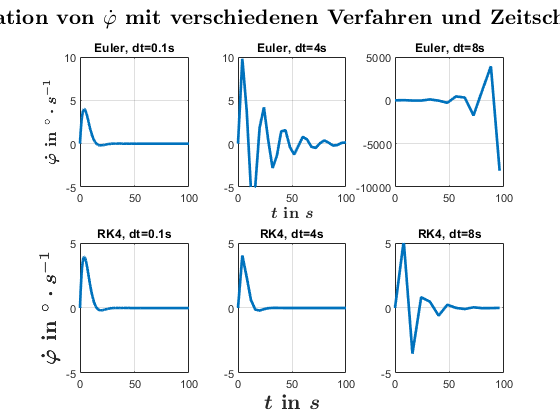

subplot(2,3,4)
lin_reg_ruku(k,l,m,g,k_reg,M_0,0.1,2)
ylim([-5 5])
ylabel("\textbf{\boldmath$\dot{\varphi}$ in \boldmath$^\circ\cdot s^{-1}$}","Interpreter","latex","FontSize",16)
hold off
subplot(2,3,5)
lin_reg_ruku(k,l,m,g,k_reg,M_0,4,2)
ylim([-5 5])
xlabel("\textbf{\boldmath$t$ in \boldmath$s$}","Interpreter","latex","FontSize",16)
hold off
subplot(2,3,6)
lin_reg_ruku(k,l,m,g,k_reg,M_0,8,2)
ylim([-5 5])
hold off
sgtitle("\textbf{Simulation von $\dot{\varphi}$ mit verschiedenen Verfahren und Zeitschritten}","Interpreter","latex","FontSize",16)

### $u$ mit eulerverfahren:

figure("name","phi")
subplot(2,3,1)
lin_reg_euler(k,l,m,g,k_reg,M_0,0.1,3)
%ylim([0 300])
ylabel("\textbf{\boldmath$u$ in \boldmath$Nm$}","Interpreter","latex","FontSize",16)
hold off
subplot(2,3,2)
lin_reg_euler(k,l,m,g,k_reg,M_0,4,3)
%ylim([0 300])
xlabel("\textbf{\boldmath$t$ in \boldmath$s$}","Interpreter","latex","FontSize",16)
hold off
subplot(2,3,3)
lin_reg_euler(k,l,m,g,k_reg,M_0,8,3)
%ylim([0 300])
hold off

### $u\;$ mit RK4

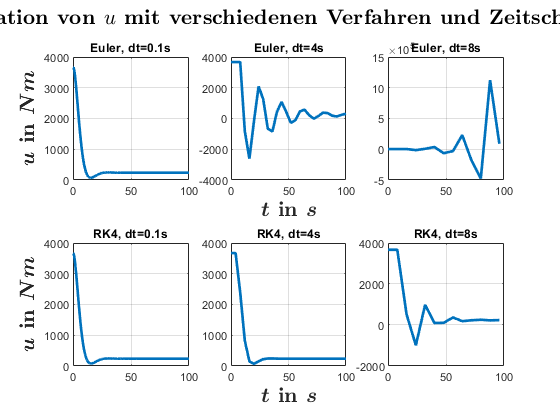

subplot(2,3,4)
lin_reg_ruku(k,l,m,g,k_reg,M_0,0.1,3)
%ylim([50 150])
ylabel("\textbf{\boldmath$u$ in \boldmath$Nm$}","Interpreter","latex","FontSize",16)
hold off
subplot(2,3,5)
lin_reg_ruku(k,l,m,g,k_reg,M_0,4,3)
%ylim([50 150])
xlabel("\textbf{\boldmath$t$ in \boldmath$s$}","Interpreter","latex","FontSize",16)
hold off
subplot(2,3,6)
lin_reg_ruku(k,l,m,g,k_reg,M_0,8,3)
%ylim([50 150])
hold off
sgtitle("\textbf{Simulation von $u$ mit verschiedenen Verfahren und Zeitschritten}","Interpreter","latex","FontSize",16)